heli.m Matlab script to be run before Simulink files ACS336 

close all;      % close all figures
clear all;      % clear workspace variables
change = 1;
load_cell = readtable('fanForceExp.csv');

format short g

## Define Discrete Time MyDAQ Dynamics

T           = 0.015;            % Sample period (s)
ADC_Vres    = 20/((2^16)-1);    % ADC voltage resolution (V/bit)
Encoder_res = 2*pi/500;         % Encoder resolution (rad/wheel count)
DAC_Vres    = 20/((2^16)-1);    % DAC voltage resolution (V/bit)
DAC_lim_u   = 10;               % DAC upper saturation limit (V)
DAC_lim_l   = 0;                % DAC enforced lower saturation limit (V)

## Define Continuous Time Helicopter Dynamics

g   = 9.81;     % Gravitational acceleration (ms^-2) 
% Rigid body parameters
% Masses and lengths
m1  = 0.0505;   % mass of fan assembly (kg)
m2  = 0.100;    % mass of counterweight (kg)
l1  = 0.110;    % distance from helicopter arm to elevation axis (m);
l2  = 0.070;    % distance from fan centres to pitch axis (m);
l3  = 0.108;    % distance from counterweight to elevation axis (m);
% Inertias
Je  = 2*m1*(l1^2)+m2*(l3^2);    % Inertia about elevation axis (kg*m^2);
Jt  = Je;                       % Travel axis inertia
Jp  = 2*m1*(l2^2);              % Pitch axis inertia
% Constraints
p_lim_u     = 80*pi/180;    % Upper pitch axis limit (rad)
p_lim_l     = -80*pi/180;   % Lower pitch axis limit (rad)
e_lim_u     = 50*pi/180;    % Upper elevation axis limit (rad)
e_lim_l     = -50*pi/180;   % Lower elevation axis limit (rad)

% %% Ex 1: DETERMINE PITCH AXIS SPRING AND DAMPING COEFFICIENTS %%%%%%%%%%%%%
% % Pitch axis spring and damping constants
k_s = 0.02;           % Spring constant (kg*m^2*s^-2)
k_d = 0.0022;           % Viscous damping (kg*m^2*s^-1)
k_e = 0.001;          % Friction coeff
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
% %% Ex 2: DETERMINE POWER AMPLIFIER GAIN AND SATURATION LIMITS %%%%%%%%%%%%%
% % Power amplifier
%NEEDS EDITING
k_a         = 1.2;   % Power amplifier voltage gain
amp_sat_u   = 12;   % Power amplifier upper saturation limit (V)
amp_sat_l   = 0;   % Power amplifier lower saturation limit (V)
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% Ex 3: CONSTRUCT FAN MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Fan voltage - thrust steady state behaviour
% NEEDS EDITING

% This is from the regression plot that was modelled from the
% experiment data

% V_ab = table2array(load_cell(:,1));          % Fan voltage input (V)
% Fss_ab = table2array(load_cell(:,2));          % Steady-state fan thrust output (N)

V_ab   = (0:0.5:10);          % Fan voltage input (V)
Fss_ab = [0 0 0 0 0 0 0.0015 0.0026 0.004 0.0056 0.0073 0.0097 0.0115 0.0145 0.0157 0.0185 0.021 0.0229 0.025 0.0276 0.0284];
% Fan voltage - thrust transient model.

tau = 0.54; % 1st order time constant

% recalc tau 

% %% Ex 4: DETERMINE EQUILIBRIUM CONTROL SIGNAL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Constant control input required to achieve hover
U_e = 4.5

U_e =           4.5


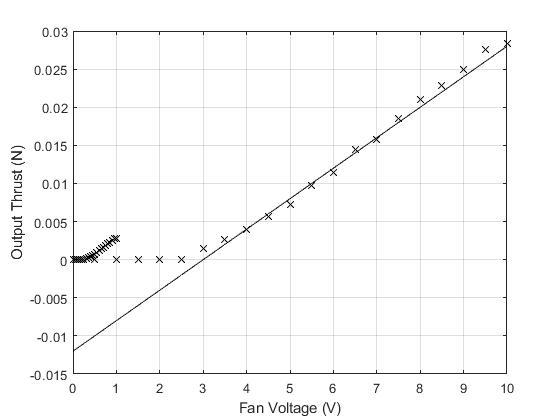


%
% 4.5

%% Ex 5: DEFINE LTI STATE-SPACE CONTROL MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  Approximate the fan voltage/thrust relationship by an affine           %
%  function of the form F_ab = alpha*V_ab+beta. Define alpha and beta.    %
figure
% alpha = 0.015;
% beta =  -0.04;
alpha = 0.004;
beta =  -0.012;

plot(V_ab/10,Fss_ab/10,'kx');           % plot raw thrust data
hold on;
plot(V_ab,Fss_ab,'kx');           % plot raw thrust data
grid on; hold on;
xlabel('Fan Voltage (V)');
ylabel('Output Thrust (N)');
plot(V_ab,alpha*V_ab+beta,'k-'); % plot linear approximation


%  State vector x:=[elev; pitch; trav; elev_dot; pitch_dot; trav_dot]     %
%  Note; these states model the dynamics of small perturbations around    %
%  the state of steady, level hover.                                      %
%  Define the control model given by x_dot = Ax + Bu, y = Cx + Du         %
A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 -k_e/Je 0 0;
     0 -(k_s/Jp) 0 0 -(k_d+k_e/Jp) 0; %-k_e/Jp
     0 (-2*l1*(alpha*k_a*U_e+beta))/Jt 0 0 0 0];

B = [0 0;
     0 0;
     0 0;
     (l1*alpha*k_a/Je) (l1*alpha*k_a/Je);
     (l2*alpha*k_a/Jp) -(l2*alpha*k_a/Jp);
     0 0];


C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];

D = [0 0;
     0 0;
     0 0];

%% Ex 6: Discrete Time Full state feedback control %%%%%%%%%%%%%%%%%%%%%%%%
% State feedback control design (integral control via state augmentation)
% x:=[elev; pitch; trav; elev_dot; pitch_dot; trav_dot; int_elev; int_trav]
% Define augmented system matrices
Cr      = [1 0 0 0 0 0
           0 0 1 0 0 0];    % Elevation and travel are controlled outputs

r       = 2;                                % number of reference inputs
n       = size(A,2);                        % number of states
q       = size(Cr,1);                       % number of controlled outputs
Dr      = zeros(q,2);
Aaug    = [A zeros(n,r); -Cr zeros(q,r)];
Baug    = [B; -Dr];


e =85.5% Penalise bad elevation behaviour 

e =          85.5



p = e*1000% Penalise bad pitch per

p =        85500



t = e*0.08% penalise travel performance

t =          6.84



edot = e*2.53% Penalise roc of elev

edot =        216.31



pdot = edot*0.0002% Penalise roc of pitch

pdot =      0.043263



tdot = edot*0.12% Penalise roc of travel

tdot =        25.958



% Define LQR weighting matrices
Qx = [e 0 0 0 0 0 0 0; % elev
      0 p 0 0 0 0 0 0; % pitch
      0 0 t 0 0 0 0 0; % travel
      0 0 0 edot 0 0 0 0; % edot
      0 0 0 0 pdot 0 0 0; % pdot
      0 0 0 0 0 tdot 0 0; % tdot
      0 0 0 0 0 0 100 0; % elev integral error
      0 0 0 0 0 0 0 15]; % travel integral error



Qx = 10*Qx

Qx =           855            0            0            0            0            0            0            0
            0     8.55e+05            0            0            0            0            0            0
            0            0         68.4            0            0            0            0            0
            0            0            0       2163.1            0            0            0            0
            0            0            0            0      0.43263            0            0            0
            0            0            0            0            0       259.58            0            0
            0            0            0            0            0            0         1000            0
            0            0            0            0            0            0            0          150




% Qx = [200*1/(e_lim_u*2) 0 0 0 0 0 0 0;
%       0 20*1/(p_lim_u*2) 0 0 0 0 0 0;
%       0 0 10*1/(2*pi) 0 0 0 0 0;
%       0 0 0 1500*1/(e_lim_u*2) 0 0 0 0;
%       0 0 0 0 1*1/(p_lim_u*2) 0 0 0;
%       0 0 0 0 0 1*1/(2*pi) 0 0;
%       0 0 0 0 0 0 20*1/(e_lim_u*2) 0;
%       0 0 0 0 0 0 0 1*1/(2*pi)]  % State penalty



Qx = [8550 0 0 0 0 0 0 0; % elev
      0 450000 0 0 0 0 0 0; % pitch
      0 0 10000 0 0 0 0 0; % travel
      0 0 0 3500 0 0 0 0; % edot
      0 0 0 0 100 0 0 0; % pdot
      0 0 0 0 0 100 0 0; % tdot
      0 0 0 0 0 0 120 0; % elev error err-edot 
      0 0 0 0 0 0 0 15]; % Error % State penalty


Qu = [1.85 0;
      0 1]*0.1;    % Control penalty

  


% Discrete-Time LQR synthesis
Kdtaug  = lqrd(Aaug,Baug,Qx,Qu,T);      % DT state-feedback controller
Kdt     = Kdtaug(:,1:n); Kidt = -Kdtaug(:,n+1:end);
%  Discrete-Time Kalman Filter Design
sysdt = c2d(ss(A,B,C,D),T,'zoh');     % Generate discrete-time system
Adt   = sysdt.a; Bdt = sysdt.b; Cdt = sysdt.c; Ddt = sysdt.d;
%  Kalman filter design; x_dot = A*x + B*u + G*w, y = C*x + D*u + H*w + v
Gdt     = 1e-1*eye(n);
Hdt     = zeros(size(C,1),size(Gdt,2)); % No process noise on measurements
Rw      = [1 0 0 0 0 0;
           0 1 0 0 0 0;
           0 0 1 0 0 0;
           0 0 0 1 0 0;
           0 0 0 0 1 0;
           0 0 0 0 0 1]*0.01;   % Process noise covariance matrix
Rv      = [0.001 0 0;
           0 0.001 0;
           0 0 0.001];   % Measurement noise covariance matrix
sys4kf  = ss(Adt,[Bdt Gdt],Cdt,[Ddt Hdt],T);
[kdfilt Ldt] = kalman(sys4kf,Rw,Rv);     % Kalman filter synthesis

## System Identification Procedure

% fanDyn=load('FanDynData.txt');
% fanDyn=rescale(fanDyn');
% stepResponse=fanDyn(:,2);
% time=fanDyn(:,1);
% signal=-fanDyn(:,3)+0.1795;

% signalAug=(signal-mean(signal));% + +0.01625
% signalAug=rescale(signalAug);

% plot(time,signalAug);
% hold on sts
% yyaxis right
% plot(time,stepResponse);

% N = length(fanDyn); % defining number of elements
% Y = signal;
% u = stepResponse;

%% System ID
% Estimating delay term
% Ts = 0.015;
% data = iddata(signalAug, stepResponse, Ts);
% delay_samples = delayest(data);
% delay_time = delay_samples * Ts;

% [signalAug stepResponse]
% sysTF = tfest(data, 1, 0, delay_time);


% compare(data, sysTF);
% resid(sysTF,data);
%% Validation
% shows that the sysf is accurate enough and we don't need to model
% noise
% sysInit = idproc('P1D','TimeUnit', 'seconds');
% 
% sysInit.Structure.Kp.Value = 1;
% sysInit.Structure.Kp.Minimum = 0;
% sysInit.Structure.Tp1.Value = 30;
% sysInit.Structure.Tp1.Maximum = 100;
% sysInit.Structure.Td.Value = 0.2;
% sysInit.Structure.Td.Minimum = 0;
% sysInit.Structure.Td.Maximum = 20;
% 
% opt = procestOptions('DisturbanceModel', 'Arma1');
% sysP1D = procest(data, sysInit, opt);
% 
% resid(sysP1D,data)


% tvect = 0:0.0001:3;    % provide any time limits you want; 
%                        % the smaller time increment the higher "accuracy"
% [val, t] = step(sysTF, tvect);
% idx_Tc = find(val>=0.63*max(val), 1, 'first');
% 
% Tc = t(idx_Tc)    % Tc which you are looking for
% tau = val(idx_Tc) % value at Tc
tau = 0.5

tau =           0.5


**Simulation Outputs**

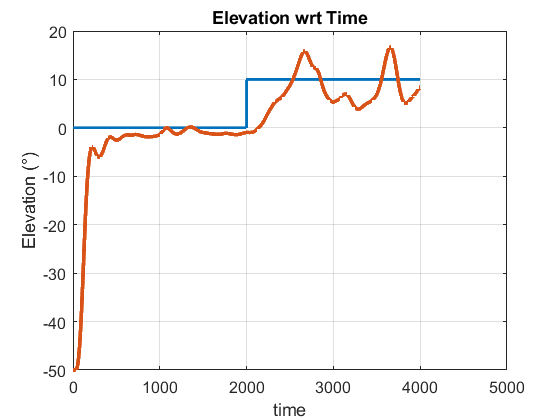

% sim('PitchSysold.slx');
% sim('OpenLoopSysold.slx');
sim('ClosedLoopSysold.slx');
FontSize = 12;

% % Pitch plot from pitch sys
% figure
% plot(pitchOutput,'LineWidth',2); grid on;
% xlabel('time');ylabel('Amplitude');
% title('Pitch Output over Time');

% % Elevation Output open loop
% figure
% plot(Elev,'LineWidth',2); grid on;
% xlabel('time');ylabel('Amplitude');
% title('Open Loop Elevation Output over Time');

% %% Travel output open loop
% figure
% plot(Trav,'LineWidth',2); grid on;
% xlabel('time');ylabel('Amplitude');
% title('Open Loop Travel Output over Time')

% %% Pitch output open loop 
% figure
% plot(Pitch,'LineWidth',2); grid on;
% xlabel('time');ylabel('Amplitude');
% title('Open Loop Pitch Output over Time');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Elev
figure('DefaultAxesFontSize',FontSize);
plot(refSignals(:,1),'LineWidth',2); grid on; hold on;
plot(outputs(:,1), 'LineWidth', 3)
%legend('Reference Signal', 'Elevation')
xlabel('time');ylabel('Elevation (°)');
title('Elevation wrt Time');

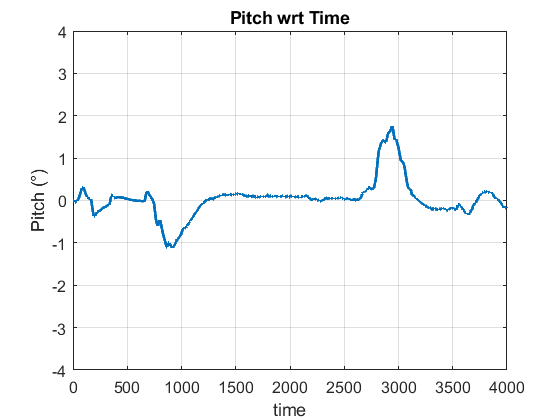


%% Pitch
figure('DefaultAxesFontSize',FontSize);
plot(outputs(:,2),'LineWidth',2); grid on; hold on; 
xlabel('time');ylabel('Pitch (°)');
xlim([0 4000]);ylim([-4 4])
title('Pitch wrt Time');

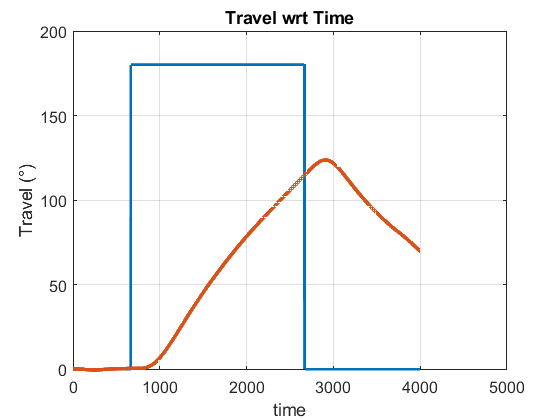


%% Travel
figure('DefaultAxesFontSize',FontSize);
plot(refSignals(:,2),'LineWidth',2); grid on; hold on;
plot(outputs(:,3), 'LineWidth', 3)
xlabel('time');ylabel('Travel (°)');
%legend('Reference Signal', 'Travel')
title('Travel wrt Time');

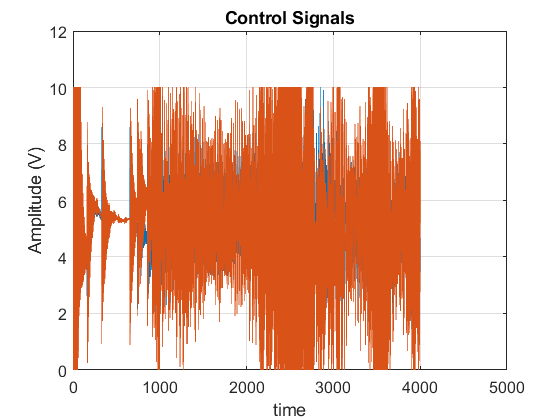


%% Control Signals
figure('DefaultAxesFontSize',FontSize);
plot(controlSignals(:,1)); grid on; hold on;
plot(controlSignals(:,2))
xlabel('time');ylabel('Amplitude (V)');
title('Control Signals');

## Output Files %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Uncomment these lines when ready to implement your feedback controller % k_amp = k_a; Vfan = V_ab; Thrust = Fss_ab;

KF_Initial = [e_lim_l 0 0 0 0 0]; Kdi_Initial = [0 0];

csvwrite('aMatrix.txt',kdfilt.a)

 csvwrite('bMatrix.txt',kdfilt.b) 

csvwrite('cMatrix.txt',kdfilt.c(size(C,1)+1:end,:))

 csvwrite('dMatrix.txt',kdfilt.d(size(C,1)+1:end,:))

 csvwrite('crMatrix.txt',Cr)

 csvwrite('KdMatrix.txt',Kdt) 

csvwrite('KdiMatrix.txt',Kidt) 

csvwrite('FanChar.txt',[Vfan,Thrust]) 

csvwrite('ModelParameters.txt',[T,U_e,l1,l2,l3,Jp,Jt,Je,m1,m2,g, k_amp, amp_sat_u, amp_sat_l, DAC_lim_u, DAC_lim_l,e_lim_l, e_lim_u, p_lim_l, p_lim_u]) 

csvwrite('KF_Initial.txt',KF_Initial) 

csvwrite('Kdi_Initial.txt',Kdi_Initial)

k_amp       = k_a;
Vfan        = V_ab;
Thrust      = Fss_ab;

KF_Initial = [e_lim_l 0 0 0 0 0]; Kdi_Initial = [0 0];
csvwrite('C:\Users\sebju\Desktop\hitlfinal\aMatrix.txt',kdfilt.a);
csvwrite('C:\Users\sebju\Desktop\hitlfinal\bMatrix.txt',kdfilt.b) ;
csvwrite('C:\Users\sebju\Desktop\hitlfinal\cMatrix.txt',kdfilt.c(size(C,1)+1:end,:));
csvwrite('C:\Users\sebju\Desktop\hitlfinal\dMatrix.txt',kdfilt.d(size(C,1)+1:end,:));
csvwrite('C:\Users\sebju\Desktop\hitlfinal\crMatrix.txt',Cr);
csvwrite('C:\Users\sebju\Desktop\hitlfinal\KdMatrix.txt',Kdt); 
csvwrite('C:\Users\sebju\Desktop\hitlfinal\KdiMatrix.txt',Kidt);
csvwrite('C:\Users\sebju\Desktop\hitlfinal\FanChar.txt',[Vfan,Thrust]);
csvwrite('C:\Users\sebju\Desktop\hitlfinal\ModelParameters.txt',[T,U_e,l1,l2,l3,Jp,Jt,Je,m1,m2,g, k_amp, amp_sat_u, amp_sat_l, DAC_lim_u, DAC_lim_l,e_lim_l, e_lim_u, p_lim_l, p_lim_u]); 
csvwrite('C:\Users\sebju\Desktop\hitlfinal\KF_Initial.txt',KF_Initial); 
csvwrite('C:\Users\sebju\Desktop\hitlfinal\Kdi_Initial.txt',Kdi_Initial);



rank(obsv(A,C));
rank(obsv(sysdt));

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     0 0 0 0 0 0;
     0 -(k_s/Jp) 0 0 -(k_d/Jp) 0;
     0 (2*l1*(alpha*k_a*U_e+beta)) 0 0 0 0];

C = [1 0 0 0 0 0;
     0 0 0 0 0 0;
     0 0 1 0 0 0];

rank(obsv(A,C))

ans =      6


obsv(A,C)

ans =             1            0            0            0            0            0
            0            0            0            0            0            0
            0            0            1            0            0            0
            0            0            0            1            0            0
            0            0            0            0            0            0
            0            0            0            0            0            1
            0            0            0            0            0            0
            0            0            0            0            0            0
            0     0.002112            0            0            0            0
            0            0            0            0            0            0
